addpath("C:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\Scripts_&_Debugging_Tools")
MyFuncs = functionsContainer;
MyFuncs.AddPathFunc("LAB"); 
py.qd_data_folder_creation.create_qd_data_directories()

Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation
Directory already exists, skipping directory creation


% Background Initilization
% Assigning the default settings to ASI
ASI_Settings.desired_exposure_time = 2;
ASI_Settings.Gain = 300;
ASI_Settings.Gamma = 50; 
ASI_Settings.Brightness = 50; 
UI_Settings = ""; 


[vid_ASI,src_ASI,vid_UI,src_UI,CamInfo] = MyFuncs.ASI_UI_CameraInit(ASI_Settings,UI_Settings);

Camera 1: ID = 1, Name = UI148xSE-M_4102700884
found UI 148x Camera (nanowire camera)
Camera 2: ID = 2, Name = ASI2600MM Pro Camera (ZWO Design)
found ASI (spectrometer camera)


triggerconfig(vid_ASI, 'manual');
triggerconfig(vid_UI, 'manual');





% Testing snapping 
tic
MyFuncs.ASI_Snap_Img(vid_ASI,src_ASI,"Background","",1800,[1 1],"");

Saved background image: background_1800mm_grating_31_01_2025_1.png
Saved background image: background_1800mm_grating_31_01_2025_2.png
Saved background image: background_1800mm_grating_31_01_2025_3.png


toc 

Elapsed time is 10.058180 seconds.


MyFuncs.ASI_Snap_Img(vid_ASI,src_ASI,"Spectrometer","Yes",1800, [1 1],"");

MyFuncs.UI_Snap_Img(vid_UI,src_UI,"Yes",[1 1])


MyFuncs.ASI_Snap_Img(vid_ASI,src_ASI,"Spectrometer","Yes",1800, [1 1],"")

src_UI =    Display Summary for Video Source Object:

      General Settings:
        Parent = [1x1 videoinput]
        Selected = on
        SourceName = input1
        Tag = [0x0 string]
        Type = videosource

      Device Specific Properties:
        BacklightCompensation = on
        Brightness = 0
        Contrast = 0
        ContrastMode = auto
        Exposure = -1
        ExposureMode = auto
        Gain = 0
        GainMode = auto
        Gamma = 100
        HorizontalFlip = off
        Sharpness = 0
        VerticalFlip = off


MyFuncs.UI_Snap_Img(vid_UI,src_UI,"Yes",[6 1])

ans = 1920×2560×3 uint8 array
ans(:,:,1) =

     7     9     9     7     7     9     7     9     8    10     8     8     8     8     8     9     8     7     9     9     8     8     9     8     8     9     8     9     8     8     9     8     8     9     8     8     8     8     8     8     8     8     9     8     8     8     7     8     8     9     8     8     8     9     9     7    10     9     9     8     7     7     8     8     9     9     9     8     8     8     8     7     9     8     8     9     8     8     8     8     8     8     8     8    10     8     8     8     9     8     9     9     9     9     8     9     8     7     8     8     8     9     8    11     8     7     9     7     8     9     8     9     9     8     9     9     8     9     8     6     8     8     8     8     9     8     8     9     8     8     8     9     8     8     7     8    10     8    10     9     9     9     9     7     8     8     8     8     9     9     8     9     8     9     8     8     9     8    10  

% Testing File Detection
% Bera Yavuz
clear;
clc;

           % adding path way for function container and python scripts used
            addpath("C:\Users\Quantum Dot\Desktop\Bera_Yavuz_GitHub\AttoCube-Project-Stuff","C:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\Scripts_&_Debugging_Tools")
        
            % adding pathway for file with images for finding excitation laser
            addpath("C:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\LED_Find_Images")

            date = MyFuncs.Fetch_Date(); % fetching today's date
            date_test =  date + "_Test"; 
            
            % Main pathway for where the background photos end up 
            pathway_main = "c:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\QD_Data\" + date_test +"\Spectrometer_ASI"; 
            filename_background = sprintf("background_%dmm_grating_%s",Spectrometer_Gratting,date);
            filename_background_saved = sprintf("%s_1.png", filename_background)
            full_pathway = fullfile(pathway_main, filename_background_saved);

if ~exist(full_pathway,"file")
    fprintf("background photo has not been taken for the day. Please take a photo before proceeding")
    return
end

addpath("C:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\Scripts_&_Debugging_Tools")
MyFuncs = functionsContainer;
MyFuncs.AddPathFunc("LAB"); 

[UI_Position_Img] = MyFuncs.ASI_Snap_Img(vid_ASI,src_ASI,"Spectrometer","Yes",1800, [1 1],"")

% Background Initilization
% Assigning the default settings to ASI
ASI_Settings.desired_exposure_time = 2;
ASI_Settings.Gain = 300;
ASI_Settings.Gamma = 50; 
ASI_Settings.Brightness = 50; 
UI_Settings = ""; 
addpath("C:\Users\Quantum Dot\Desktop\Bera Yavuz - ANC300 Movement and Images\Scripts_&_Debugging_Tools")
MyFuncs = functionsContainer;
MyFuncs.AddPathFunc("LAB"); 

[vid_ASI,src_ASI,vid_UI,src_UI,CamInfo] = MyFuncs.ASI_UI_CameraInit(ASI_Settings,UI_Settings);

Camera 1: ID = 1, Name = UI148xSE-M_4102700884
found UI 148x Camera (nanowire camera)
Camera 2: ID = 2, Name = ASI2600MM Pro Camera (ZWO Design)
found ASI (spectrometer camera)


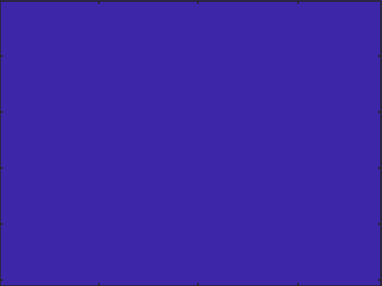

fig = figure();
ax = axes('Parent', fig, 'Units', 'normalized', 'Position', [0 0 1 1]);
camsize = vid_UI.VideoResolution;
im = image(zeros(camsize), 'Parent', ax);


preview(vid_UI, im);     %pass the image object to preview!

Unrecognized function or variable 'cam'.

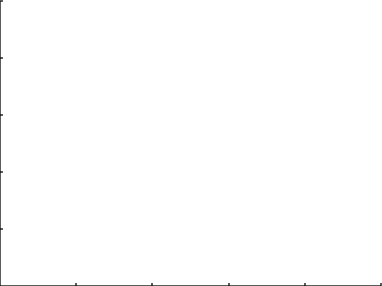

screenSize = get(0, 'ScreenSize'); % gets pixel resolution of screen
                dimensions_UI = vid_UI.VideoResolution;
                width = dimensions_UI(1);
                height = dimensions_UI(2);
                figWidth = width/4;
                figHeight = height/4;
                left = (screenSize(3) - figWidth) * 0.75; % Shift right
                bottom = (screenSize(4) - figHeight) / 2; % Center vertically

                previewFig = figure('Position', [left, bottom, figWidth, figHeight]);
                previewAx = axes('Parent', previewFig, 'Position', [0, 0, 1, 1]);


                 preview(vid_UI);

Error using imaqdevice/preview (line 129)
The specified image handle must be a valid 1xN image object handle, where N represents the specified video input object's length.